# Computer Aided Design Based Shape Optimization

This repository showcases how to use MATLAB's API `checkGradients` to validate analytically derived expressions of gradients with  application to sensitivity analysis for shape optimization problems in  structural mechanics.

Author: Deha Şen Köse, dehasenkose@gmail.com

## Define General Data for Gradient Validation and Shape Optimization

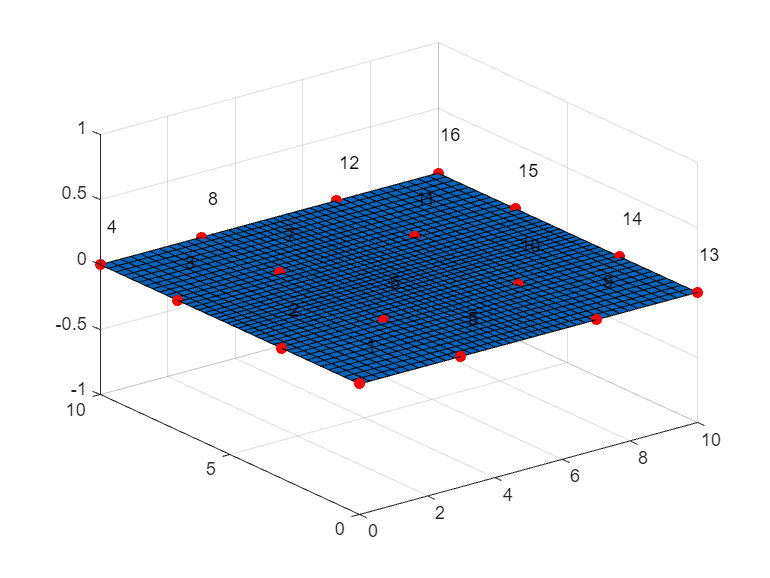

% Define the control points in x-direction.
cpX = [0,0;
       3,0;
       7,0;
       10,0];

% Get the number of control points in x-direction.
numCPX = height(cpX);

% Define the control points in y-direction.
cpY = [0,0;
       0,3;
       0,7;
       0,10];

% Get the number of control points in y-direction.
numCPY = height(cpY);

% Create the surface control points.
cp = generateSurfaceCPs(cpX,cpY,true);

% Get the number of total control points.
numCP = height(cp);

% Define the polynomial orders.
pxi = 2;
peta = 2;

% Define the knot vectors.
kntXi = [0,0,0, 0.5, 1,1,1];
kntEta = [0,0,0, 0.5, 1,1,1];

% Define the material properties and thickness.
materialProp.E = 210E3;
materialProp.nu = 0.3;
materialProp.t = 0.1;

% Define the distributed load vector.
dload = [0, -20];

% Define the homogeneous dofs.
homdofs = 1:numCPY*2;

% Visualize the plate.
s = computeBSplineSurface(kntXi, pxi, kntEta, peta, cp, [40,40], true, NaN);

## Validation of the Gradients

% Create a flat array for control point coordinates.
dvFlat = zeros(height(cp)*2,1);
for ii=1:height(cp)
    dvFlat(2*ii-1, 1) = cp(ii,1);
    dvFlat(2*ii, 1) = cp(ii,2);
end

% Define the design variable degrees of freedom to compute the gradients 
% for each control point x- and y-coordinate.
dvdof1 = 1:numCP*2;

% Define the function handle for validation of gradients.
valFun = @(designVariables) strainEnergyFun(kntXi, kntEta, pxi, peta, cp,...
    materialProp, dload, homdofs, dvdof1, false, designVariables, ...
    "DistributedLoad", [], false, []);

validity = checkGradients(valFun, dvFlat, Display="on");

____________________________________________________________

Objective function derivatives:
Maximum relative difference between supplied 
and finite-difference derivatives = 1.08938e-08.

checkGradients successfully passed.
____________________________________________________________



### Normal Shape Optimization of a Plane Stress Plate with Symmetric Parameter Linking

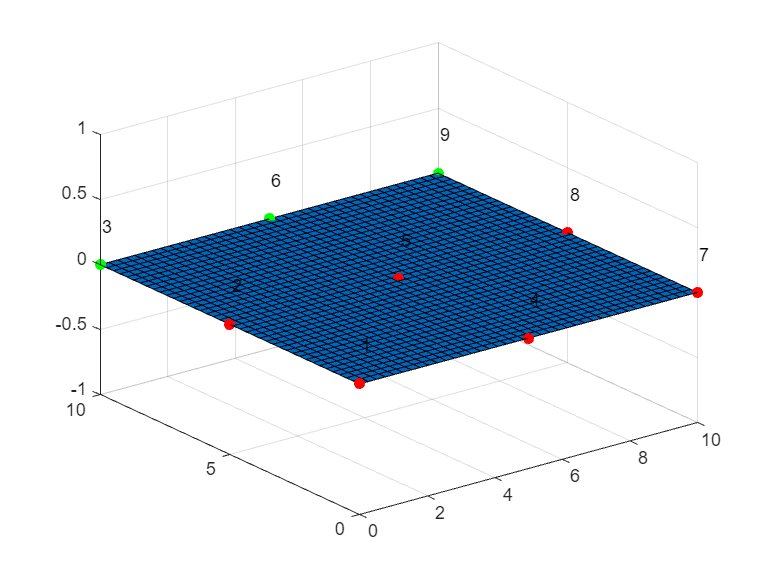

% Define the control points in x-direction.
cpXSym = [0,0;
        5,0;
        10,0];
% Get the number of control points in x-direction.
numCpXSym = height(cpXSym);

% Define the control points in y-direction.
cpYSym = [0,0;
        0,5;
        0,10];
% Get the number of control points in y-direction.
numCpYSym = height(cpYSym);

% Generate the control points.
cpSSym = generateSurfaceCPs(cpXSym,cpYSym,true);
cpSOrig = cpSSym;

% Define the knot vectors.
kntXi = [0,0,0,1,1,1];
kntEta =[0,0,0,1,1,1];

% Define the polynomial orders.
pxi = 2;
peta = 2;

% Define the material parameters.
materialProp.E = 210E3;
materialProp.t = 0.01;
materialProp.nu = 0.3;

% Plot the original problem
surfaceSymOrig = computeBSplineSurface(kntXi,pxi,kntEta,peta,cpSOrig,[40,40],true,[6,12,18]);

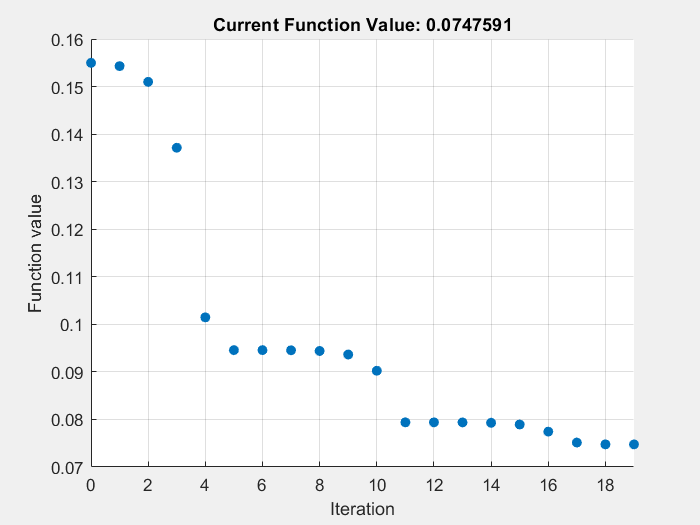


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% Define the distributed load.
dload = [0,-200];

% Define the homogeneous dofs
homdofs = 1:numCpYSym*2;

% Create a vector of design variables.
dvFSym = zeros(height(cpSSym)*2,1);
for ii=1:height(cpSSym)
    dvFSym(2*ii-1, 1) = cpSSym(ii,1);
    dvFSym(2*ii, 1) = cpSSym(ii,2);
end
% Define the design variable dofs.
dvDofSym = [6,12,15,18];
% Get the design variable initial values.
dvFoptSym = dvFSym(dvDofSym);
ivSym = dvFoptSym;

% Create the options for the optimizer.
optionsSym = optimoptions("fmincon","Algorithm","sqp","SpecifyObjectiveGradient",true,...
    "StepTolerance",1e-8,'PlotFcns',@optimplotfval);

% Define the objective function.
objFunSym = @(dvFoptSym) strainEnergyFun(kntXi, kntEta, pxi, peta, cpSSym, materialProp,...
    dload, homdofs, dvDofSym, false, dvFoptSym, "DistributedLoad", [], true, [1,4,7]);

% Redefine the initial volume.
initialVolume = 100*materialProp.t;

% Redefine the percentage.
percentage = 1.6;

% Define the non-linear constraint function handle for the optimizer.
volumeFunHandle = @computeSurfaceVolume;
nonlinconSym = @(dvFoptSym) volumeConstraint...
         (volumeFunHandle, kntXi, kntEta, pxi, ...
          peta, cpSSym, materialProp, dvFoptSym,...
          dvDofSym, initialVolume, percentage, numCpYSym, true, [1,4,7], "UpperBound", [], []);

% Define the upper and lower bounds for the control points.
lb = [6,6,10,6];
ub = [13,Inf,Inf,Inf];

% Run the optimizer.
[x, ~] = fmincon(objFunSym,ivSym,[],[],[],[],lb,ub,nonlinconSym,optionsSym);

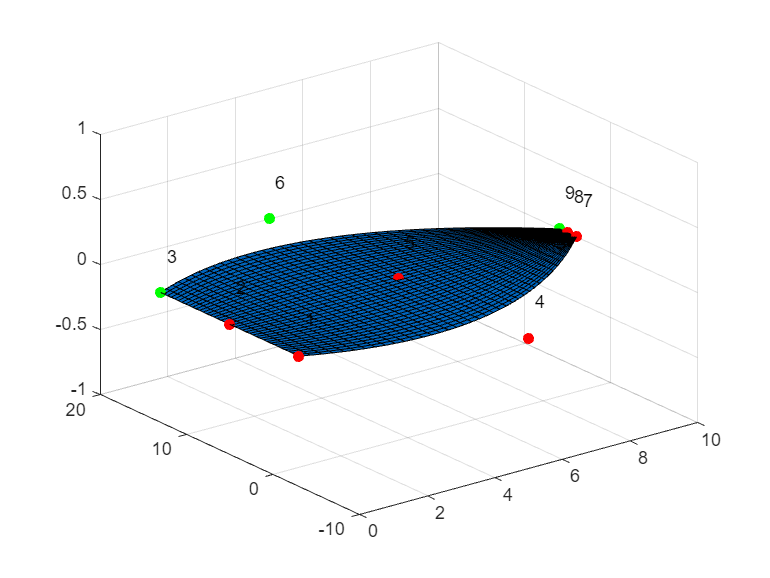

% Add the solutions into a matrix to visualize.
cpSSym2 = cpSSym;
for ii=1:length(x)
    dof = dvDofSym(ii);
    r = ceil(dof/2);
    if mod(dof,2) == 0
        c = 2;
    else
        c = 1;
    end
    cpSSym2(r,c) = x(ii);
end


cpsymNew = symmetryFun(cpSOrig,cpSSym2,numCpYSym,[1,4,7]);
surface = computeBSplineSurface(kntXi,pxi,kntEta,peta,cpsymNew,[40,40],true,[6,12,18]);

svSym = computeSurfaceVolume(kntXi, kntEta, pxi, peta, cpsymNew, materialProp);

### Optimization Using Sensitivity Weighting

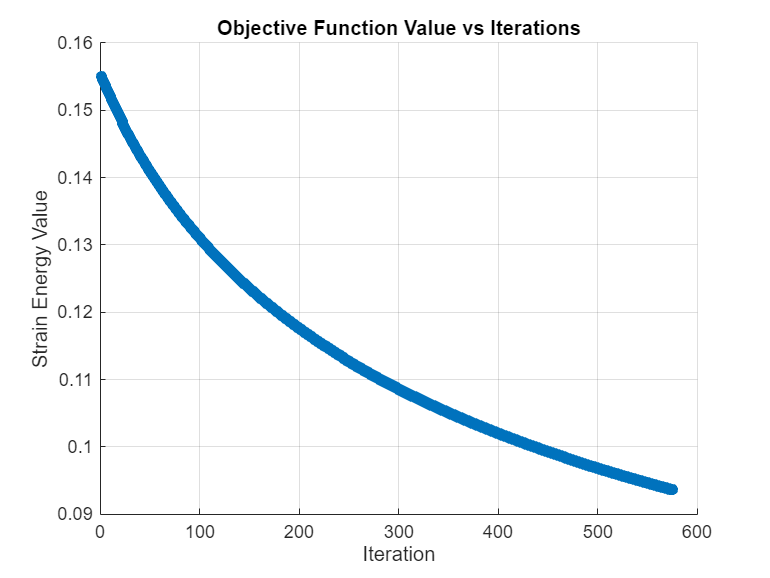

% Prepare data
dvFoptSymW = dvFoptSym([1,2,4]);
dvDofSymW = dvDofSym([1,2,4]);
numIter = 1000;
f = zeros(numIter,1);
dvFoptSymWc = dvFoptSymW;

% Use the Newton's update rule.
for ii=1:1000

    [f(ii),g,~,A] = strainEnergyFun(kntXi, kntEta, pxi, peta, cpSSym, materialProp,...
    dload, homdofs, dvDofSym, false, dvFoptSymW, "DistributedLoad", [], true, [1,4,7]);

    A_inv = diag(A);
    A_inv = 1./A_inv;
    A_inv = diag(A_inv);
    s = -10*A_inv([3,6,9],[3,6,9])*g([1,2,4]);
    dvFoptSymW = dvFoptSymW + s;
    
    % Check for the constraint violation.
    if dvFoptSymW(1) >= 13
        break
    end
end
f(ii+1:end) = [];

% Plot the objective function.
figure
scatter(1:ii,f,"filled")
title("Objective Function Value vs Iterations")
xlabel("Iteration")
ylabel("Strain Energy Value")
grid on

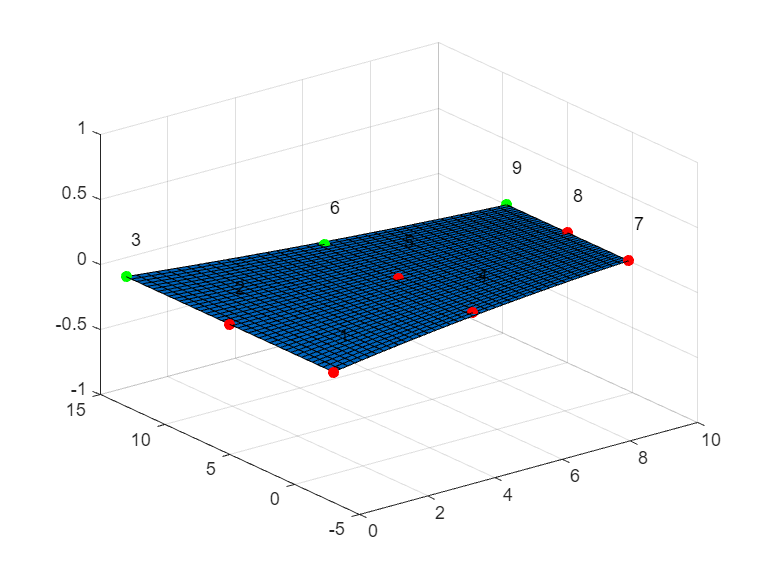

% Add the solutions into a matrix to visualize.
cpSSymW = cpSSym;
for jj=1:length(dvFoptSymW)
    dof = dvDofSymW(jj);
    r = ceil(dof/2);
    if mod(dof,2) == 0
        c = 2;
    else
        c = 1;
    end
    cpSSymW(r,c) = dvFoptSymW(jj);
end

% Prepare the data for surface plotting
cpsymNewW = symmetryFun(cpSOrig,cpSSymW,numCpYSym,[1,4,7]);
surface = computeBSplineSurface(kntXi,pxi,kntEta,peta,cpsymNewW,[40,40],true,[6,12,18]);